Load & Choose a dataset (must be run at the very start)

chosenDataset = "tubes";

% Obtain the file location of the dataset. 
% ***IMPORTANT***
% This file location stored is a RELATIVE path!!!
% For this script to run, your active path must be set to where
% the MPDD dataset is stored on your local system.
fileLoc = sprintf("MPDD/%s", chosenDataset);
fileLocGT = sprintf("MPDD/%s_ground_truth", chosenDataset);

% Creates an image Datastore to store all images of specified subset type.
% The image Datastore is setup to specifically look for images with certain file
% extensions that are common for images (i.e. jpg, png, etc.)
ds = imageDatastore(fileLoc, 'IncludeSubfolders',true, 'LabelSource','foldernames', ...
    'FileExtensions', ["*.jpg", "*.png", "*.tiff"]);
dsGT = imageDatastore(fileLocGT, 'IncludeSubfolders',true, 'LabelSource','foldernames', ...
    'FileExtensions', ["*.jpg", "*.png", "*.tiff"]);

Train a model on the chosen dataset (will also output a validation set that can be used for the batch testing function

% Creates an AI Model in local directory called "tubeClassifierNet.mat"
% returns a test set that was used for validation
testDS = training(ds);

Detected 4 classes to learn.
    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:09       0.0001                            3.1337                                    4.4444
            1        1       00:00:09       0.0001          2.4075                                  12.5                      
           10        1       00:00:45       0.0001          1.3697           0.96604               68.75                62.222
           20        2       00:01:16       0.0001         0.31724           0.41774               93.75                93.333
           30        3       00:01:48       0.0001         0.12504           0.18794               93.75                95.556
           40        4       00:02:19       0.0001        0.097427           0.120

Perform a batch test on the test set

labels = 1×4 string array
    "good"    "color_mismatch"    "defective_length"    "malformed_metal"


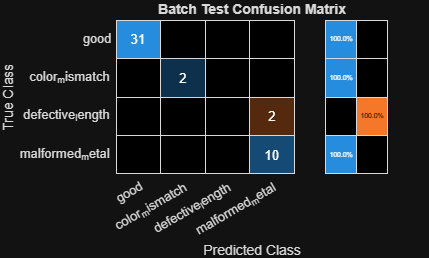

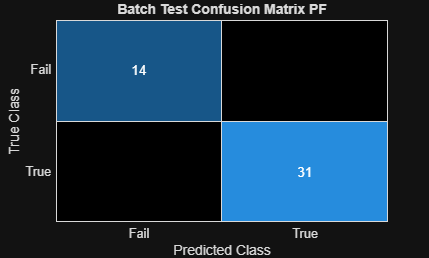

Actual Yield: 68.9%
Predicted Yield 68.9%

Defect Rate: 31.1%
Escaped Defect Rate 0.0%



% Inspects the chosen batch using the trained AI model, outputs a confusion
% matrix
runBatchInspection(testDS);

Test individual images with the trained model

IMPORTANT: need to move all good images to the testing good folder, which means we can remove the testing folder altogether, this will make selecting images far easier, but would also require us to rename images in mass

grey =     0.1200    0.1200    0.1200


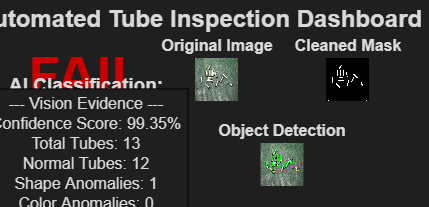

% Adjust below controls to choose a specific image of interest
imageType = "malformed_metal";
fileLoc = sprintf("MPDD/%s/test/%s", chosenDataset, imageType);


% Temporarily use datastore until we can re-organize the images to make
% this cleaner overall.
tempDS = imageDatastore(fileLoc, 'IncludeSubfolders',true, 'LabelSource','foldernames', ...
    'FileExtensions', ["*.jpg", "*.png", "*.tiff"]);
numFiles = numel(tempDS.Files);
imgNum = 42;

img = readimage(tempDS, imgNum);
reportData = singleImageInspectionFunction(img, true);
displayInspectionOutput(img, reportData);

#FIXME - temporary code for determining folder location, will be put to use once folder is re-organize and renamed

% test
scriptPath = fileparts(mfilename('fullpath'))
currentDir = pwd;